# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: - Clasificador de Dígitos Usando HOG Features

Este ejemplo muestra cómo clasificar dígitos utilizando características HOG y un clasificador SVM multiclase.

La clasificación de objetos es una tarea importante en muchas aplicaciones de visión por ordenador, incluyendo la vigilancia, la seguridad en el automóvil y la recuperación de imágenes. Independientemente del tipo de objeto que se clasifique, el procedimiento básico para crear un clasificador de objetos es el siguiente

- Adquirir un conjunto de datos etiquetados con imágenes del objeto deseado.

- Dividir el conjunto de datos en un conjunto de entrenamiento y un conjunto de test.

- Entrenar el clasificador utilizando las características extraídas del conjunto de entrenamiento.

- Probar el clasificador utilizando las características extraídas del conjunto de test.

El **objetivo** de este ejercicio es  clasificar dígitos numéricos utilizando características `HOG` (`Histogram of Oriented Gradient`) y un clasificador multiclase `SVM` (`Support Vector Machine`). Este tipo de clasificación se utiliza a menudo en muchas aplicaciones de reconocimiento óptico de caracteres (`OCR`).

**Nota**: El ejemplo utiliza la función `fitcecoc` de la `Statistics and Machine Learning Toolbox™` y la función `extractHOGFeatures` de la `Computer Vision Toolbox™`. (Estas toolbox deberían estar instaladas)

close all;
clear all; 
clc; 
addpath(genpath(pwd));

## (Etapa 1) Base de datos.

Se va a utilizar un conjunto de imágenes de dígitos sintéticos de 16x16 píxeles, que están contenidos en `digits.zip,` (también se puede obtener de `Computer Vision Toolbox™`). 

El conjunto de **entrenamiento** consta de 101 imágenes para cada uno de los 10 dígitos (**1010** imágenes). Cada una de las imágenes de entrenamiento contiene un dígito rodeado de otros dígitos, lo que imita cómo se ven normalmente los dígitos juntos. 

Aunque no es el conjunto de datos más representativo, hay suficientes datos para entrenar y probar un clasificador, y mostrar la viabilidad del enfoque.

**Se Pide:**

- Muestre 3 imágenes del conjunto de entrenamiento tomadas de forma aleatoria (puede utilizar la función [randi](https://es.mathworks.com/help/matlab/ref/double.randi.html) para obtener número enteros de forma aleatoria).

% Datos para TRAIN
% (opción a) a partir de Computer Vision Toolbox™
% trainingSet_path = fullfile(toolboxdir('vision'),'visiondata','digits','synthetic');
% (opción b) a partir del fichero digits.zip
trainingSet_path = 'digits/synthetic/';

trainingSet = imageDatastore(trainingSet_path,'IncludeSubfolders',true,'LabelSource','foldernames');
countEachLabel(trainingSet)

% COMPLETE el codigo para:
% mostrar 3 imágenes de entrenamiento tomadas de forma aleatoria
figure;
for i=1:3
    subplot(1,3,i);
    % COMPLETE AQUÍ!!!
end


## (Etapa 2) **Extracción de características**.

Los datos utilizados para entrenar el clasificador son vectores de características HOG extraídos de las imágenes de entrenamiento y que se pueden obtener con la función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures). 

HOG por defecto utiliza por defecto un tamaño de celda (`CellSize``)de` `[8 8]` y construye histogramas de `9 bins` a apartir de la imagen gradiente. Después contruye bloques de `16×16` (4 histogramas) y forma un vector de `36×1` elementos, que son normalizados. Este proceso lo repite haciendo 7 desplazamientos horizontales y 15 verticales de los bloques de `16×16`, lo que hace un total de 105 bloques de vectores de `36×1` elementos, luego la dimensión del vector final es `36x105=``3780`` elementos`.

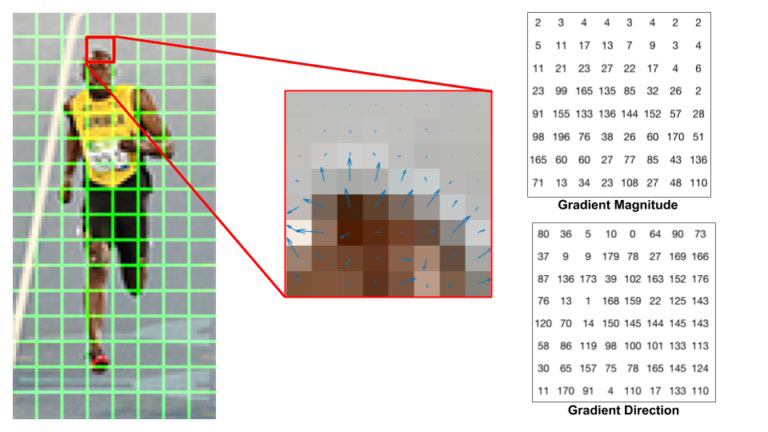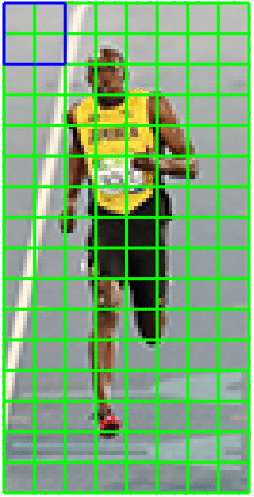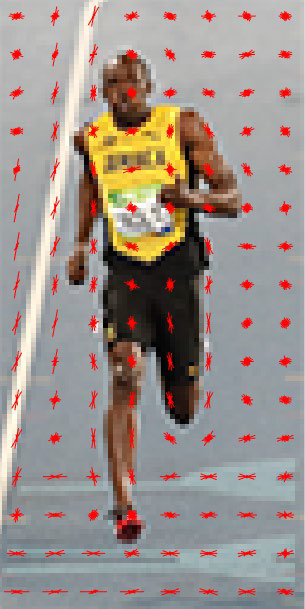

La función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures) puede devolver el resultado de visualización. Variando el parámetro del tamaño de la celda HOG (CellSize`)` y visualizando el resultado, se puede ver el efecto que tiene el parámetro del tamaño de la celda en la cantidad de información codificada en el vector de características.

**Se pide:**

- Uno de los parámetros que hay que cambiar es el tamaño de celda (`CellSize``)`, por defecto es `[8 8]`, dado que las imágenes son de 16x16 píxeles este tamaño codifica insuficiente información, por lo que debe cambiar el tamaño a [4 4] y luego a [2 2], visualizar en ambos casos el resultado para la imagen 1 y elijir uno de los dos valores utilizados para continuar con la práctica.

% (a) Cálculo del tamaño del vector de características de HOG

% se lee la primera imagen del dataset de train
image_num = 1;
img = readimage(trainingSet,image_num);

% tamaño de la celda HOG 
CellSize = [ ]; % RELLENAR AQUí!!!

% valores por defecto de extractHOGFeatures
BlockSize = [2 2];
BlockOverlap = ceil(BlockSize/2);
NumBins = 9;
BlocksPerImage = floor((size(img(:,:,1))./CellSize - BlockSize)./(BlockSize - BlockOverlap) + 1);
% tamaño del vector de características de HOG
hogFeatureSize = prod([BlocksPerImage, BlockSize, NumBins]);

% extracción del vector de caracterísitcas de HOG
[hog_vect, hog_vis] = extractHOGFeatures(img,'CellSize',CellSize);

% visualización del vector de caracterísitcas de HOG
figure; 
subplot(1,3,1);
imshow(img);
title(['image ' trainingSet.Labels(random_num)])
grey = im2gray(img);
% Apply pre-processing steps
bw = imbinarize(grey);
subplot(1,3,2);
imshow(bw);
title('binary')
% Visualize the HOG features
subplot(1,3,3);  
plot(hog_vis); 
title(sprintf('CellSize = [%d %d]\nLength = %d',CellSize(1,1),CellSize(1,2),hogFeatureSize));

**Se pide:**

- Complete el bucle que extrae las características HOG de cada imagen del conjunto de entranmiento con la función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures), asegurándose de que utilice el tamaño de celda `CellSize`, y guarde los vectores en la variable llamada `trainingFeatures`. 

% (b) Extracción de caracterísitcas para el conjunto de datos de TRAIN

% Se calcula el número de elementos de la matriz con 'numel'
numImagesTrain = numel(trainingSet.Files);
trainingFeatures = zeros(numImagesTrain,hogFeatureSize,'single');

for i = 1:numImagesTrain
    % se lee cada imagen
    img = []; % COMPLETAR AQUÍ!!!!
    % se extrae el descriptor HOG y se guarda
    trainingFeatures(i, :) = extractHOGFeatures( );  % COMPLETAR AQUÍ!!!!  
end

% se obtienen las etiquetas para cada imagen.
trainingLabels = trainingSet.Labels;


## (Etapa 3) Entrenamiento

El entrenamiento del clasificador de dígitos se realiza con la función [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html), que ajustar modelos multiclase para máquinas de vectores soporte (SVM) u otros clasificadores. Los datos para entrenar son las características HOG extraídas del conjunto de entrenamiento. Se puede configurar el esquema de codificación multiclase como `'one-vs-one' `ó `'one-vs-all'`.

**Se pide:**

- Rellene la función [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html) para que realice el entrenamiento, utilizando una codificación ('`Coding'`) 'One-vs-One' para crear el clasificador multiclase utilizando SVMs binarias. El modelo del clasificador se guardará en la variable llamada **MdlClassifier**`.`

**Nota**: para utilizar la función [`fitcecoc`](https://es.mathworks.com/help/stats/fitcecoc.html?searchHighlight=fitcecoc&s_tid=srchtitle_support_results_1_fitcecoc) hay que tener instlada la Toolbox™ `Statistics and Machine Learning`.

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.
MdlClassifier = fitcecoc(); % COMPLETAR AQUÍ!!!!


## (Etapa 4) Predicción

Se obtienen las predicciones del modelo entrenado para todas las imágenes de test con la función [predict](https://es.mathworks.com/help/stats/classificationecoc.predict.html).

El conjunto de **test** consta de 12 imágenes por dígito (**120** imágenes). Para las pruebas, se utilizan escaneos de dígitos escritos a mano para validar el rendimiento del clasificador con datos diferentes a los de entrenamiento. 

**Se pide:**

- Cargue el conjunto de datos de **test **(`'digits/handwritten/'`), al igual que ha realizado en la etapa 1.

- Extraiga las características HOG para este conjunto de datos, del mismo modo se ha realizado en la etapa 2 (¡OJO! debe tener el mismo tamaño de celda **CellSize**, por lo que debe haber ejecutado previamente la Etapa 2).

- Por último, obtenga las predicciones para cada una de las imagenes de test con la función [predict](https://es.mathworks.com/help/stats/classificationecoc.predict.html) y guardelas en la variable llamada `predictedLabels`.

% Datos para TEST  % COMPLETAR AQUÍ!!!!


% Predicciones de clase utilizando las características HOG de las imagenes de test.
predictedLabels = predict( ); % COMPLETAR AQUÍ!!!!

## (Etapa 5) Resultados

Se debe evaluar el clasificador utilizando los resultados obtenidos para el conjunto de test, generando la matriz de confusión y calculando a partir de ésta  parámetros como: `Accuracy, Macro_Recall, Macro_Precision y Macro_F1_score`.

**Se pide:**

- Calcule la matriz de confusión con la función [confusionmat](https://es.mathworks.com/help/stats/confusionmat.html) o [confusionchart](https://es.mathworks.com/help/releases/R2025a/deeplearning/ref/confusionchart.html) y guarde el resultado en una variable llamada `CM`. 

% Matriz de Confusión
CM =  % COMPLETAR AQUÍ!!!!
 

**Se pide:**

- Codifique una función llamada `multiclass_scores` a la que se le pase la matriz de confusión `CM` y devuelva dos arrays: el primero llamado `ClassScores` de tamaño *Mx3*, donde *M* es el número filas que se corresponde con el número de clase (en este caso 10 clases, una para cada dígito) y tres columnas en las que está el cálculo de: `Recall, Precision` y `F1_Score` para cada una de las clases. El segundo array llamado MacroScores es de tamaño 1x3 y contiene los siguientes valores:` Macro_Recall, Macro_Precision y Macro_F1_Score`.

% Scores
[ClassScores, MacroScores] = multiclass_scores(CM);

labels = categories(categorical(0:1:9));
CScores = array2table(ClassScores,'RowNames',labels,'VariableNames',{'Recall','Precision','F1_Score'})
GScores = array2table(MacroScores,'RowNames',{'Global'},'VariableNames',{'Macro-Recall', 'Macro-Precision','Macro-F1'})


## **MNIST**

**Se pide:**

- Vuelva entrenar el clasificador (completando todos los pasos anteriores) con un conjunto de datos más representativo, el dataset de MNIST, que contiene un conjunto de entrenamiento de 60.000 imágenes de caracteres escritos a mano ('`train-images.idx3-ubyte'`) y sus respectivas etiquetas ('`train-labels.idx1-ubyte'`), y un conjunto de test de 10.000 imágenes ('`t10k-images.idx3-ubyte'`), y sus respectivas etiquetas ('`t10k-labels.idx1-ubyte`'). Para leer estos datos se proporciona la función `readMNIST` cuyos parámetros se explican en la cabecera de la propia función. Un ejemplo de uso sería la siguiente instrucción que lee las 100 primeras imágenes y sus correspondientes etiquetas del  conjunto de datos de test.

`               [imgs labels] = readMNIST('t10k-images.idx3-ubyte', 't10k-labels.idx1-ubyte', 100, 0)`

    **Nota**: esta función carga en un dos arrays,` imgs y labels`, todas las imágenes y sus respectivas etiquetas.

%% MNIST


# FUNCIONES

function [ClassScores, GlobalScores] = multiclass_scores(CM)

    Recall = [];
    Precision = [];
    F1_Score = [];
    for i=1 : size(CM,1)
        Recall(i) = []; % COMPLETAR AQUÍ!!!!
        Precision(i) = []; % COMPLETAR AQUÍ!!!!
        F1_Score(i) = []; % COMPLETAR AQUÍ!!!!
    end

    ClassScores = [Recall' Precision' F1_Score'];
      
    Macro_Recall = []; % COMPLETAR AQUÍ!!!!
    Macro_Precision = []; % COMPLETAR AQUÍ!!!!
    Macro_F1 = []; % COMPLETAR AQUÍ!!!!

    GlobalScores = [Macro_Recall Macro_Precision Macro_F1];
end
